# Ecuaciones lineales de primer orden  

# Problemas de valor inicial

Use separation of variables to find solutions of the IVP (initial value problem) given by y(0) = 1 and the following differential equations:

(a)$\frac{\mathrm{d}}{\mathrm{d}t}y=t$    (b) $\frac{\mathrm{d}}{\mathrm{d}t}y=t^2 y$    (c) $\frac{\mathrm{d}}{\mathrm{d}t}y=2\left(t+1\right)y\;$

% t en [0,2]
y0 = 1;
t0 = 0;
tf = 2;
h = .1;

% f1 = @(t,y) t;
syms y(t);
eqn = diff(y,t) == t;
cond = y(0) == 1;
vSym(t) = dsolve(eqn,cond); 
f1 = matlabFunction(vSym(t));
fplot(f1,[0 2]);
f1 = @(t,y) t;
[t11,y11] = TerPar_odeEuler(f1,t0,y0,h,tf)%TerPar_odeEuler(f, to, yo, h, tf)

t11 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y11 =     1.0000    1.0000    1.0100    1.0300    1.0600    1.1000    1.1500    1.2100    1.2800    1.3600    1.4500    1.5500    1.6600    1.7800    1.9100    2.0500    2.2000    2.3600    2.5300    2.7100    2.9000


[t12,y12] = TerPar_RK4(f1,t0,y0,h,tf)%TerPar_RK4(f,t0,y0,h,tf)

t12 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y12 =     1.0000    1.0050    1.0200    1.0450    1.0800    1.1250    1.1800    1.2450    1.3200    1.4050    1.5000    1.6050    1.7200    1.8450    1.9800    2.1250    2.2800    2.4450    2.6200    2.8050    3.0000


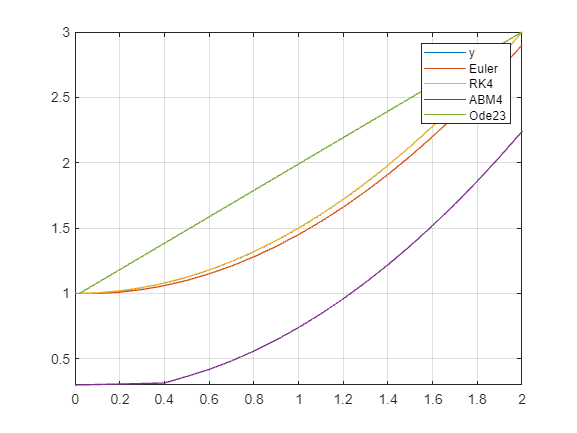

[t13,y13] = TerPar_AMB4(f1,y0,t0,tf,h);%TerPar_AMB4(f,y0,t0,tf,h)
[t14,y14] = TerPar_ode23MVC(f1,y0,t0,tf,10^(-5));%(f,y0,t0,tf,tol)
hold on
plot(t11,y11);
plot(t12,y12);
plot(t13,y13);
plot(t14,y14);
legend(["y", "Euler", "RK4", "ABM4", "Ode23"]);
grid on
hold off

% f2 = @(t,y) t.^2*y;
syms y(t);
eqn = diff(y,t) == t^2*y;                       
cond = y(0) == 1;
vSym(t) = dsolve(eqn,cond);
f2 = matlabFunction(vSym(t));
fplot(f2,[0 2]);
f2 = @(t,y) t.^2*y;
[t,y2(1,:)] = odeEuler(f2,y0,t0,tf,h);
[~,y2(2,:)] = odeMidpoint(f2,y0,t0,tf,h);
[~,y2(3,:)] = odeHeun(f2,y0,t0,tf,h);
[~,y2(4,:)] = odeRK4(f2,y0,t0,tf,h)
hold on
plot(t,y2);
legend(["y", "Euler", "Midpoint", "Heun", "RK4"]);
grid on
hold off

% f3 = @(t,y) 2*(t+1)*y;
syms y(t);
eqn = diff(y,t) == 2*(t+1)*y;
cond = y(0) == 1;
vSym(t) = dsolve(eqn,cond); 
f3 = matlabFunction(vSym(t));
fplot(f3,[0 2]);
f3 = @(t,y) 2*(t+1)*y;
[t,y3(1,:)] = odeEuler(f3,y0,t0,tf,h);
[~,y3(2,:)] = odeMidpoint(f3,y0,t0,tf,h);
[~,y3(3,:)] = odeHeun(f3,y0,t0,tf,h);
[~,y3(4,:)] = odeRK4(f3,y0,t0,tf,h)
hold on
plot(t,y3);
legend(["y", "Euler", "Midpoint", "Heun", "RK4"]);
grid on
hold off





$$y^{\prime } =y\left(1-y\right)$$
      
$$y\left(0\right)=1/2$$


% t en [0,6]
y0 = 1/2;
t0 = 0;
tf = 6;
h = 1;

syms y(t);
eqn = diff(y,t) == y*(1-y);
cond = y(0) == 1/2;
vSym(t) = dsolve(eqn,cond); 
f = matlabFunction(vSym(t));
fplot(f,[t0 tf]);
f = @(t,y) y*(1-y);
[t,y4(1,:)] = odeEuler(f,y0,t0,tf,h);
[~,y4(2,:)] = odeMidpoint(f,y0,t0,tf,h);
[~,y4(3,:)] = odeHeun(f,y0,t0,tf,h);
[~,y4(4,:)] = odeRK4(f,y0,t0,tf,h)
hold on
plot(t,y4);
legend(["y", "Euler", "Midpoint", "Heun", "RK4"]);
grid on
hold off


$$y^{\prime } =k{\left(a_0 -y\right)}^2 \left(b_0 -y/2\right)$$
     
$$y\left(0\right)=0$$


$k=0\ldotp 00713$; $a_0 =4$; $b_0 =1$

% t en [0,400]
y0 = 0;
t0 = 0;
tf = 400;
h = 5;

k = .00713;
a = 4;
b = 1;

syms y(t);
eqn = diff(y,t) == k*((a-y)^2)*(b-y/2);
cond = y(0) == 0;
Symb(t) = dsolve(eqn,cond)
f = matlabFunction(Symb(t));
fplot(f,[t0 tf]);

f = @(t,y) k*(a-y).^2*(b-y/2);
[t,y5(1,:)] = odeHeun(f,y0,t0,tf,h);
[~,y5(2,:)] = odeRK4(f,y0,t0,tf,h);
hold on
plot(t,y5);
legend(["y", "Heun", "RK4"]);
grid on
hold off

Resuelve el siguiente problema de valor inicial en el intervalo de $t=0$ a $t=2$


$$y^{\prime } =yt^2 -1\ldotp 1y$$
      
$$y\left(0\right)=1$$


% Solucion analitica
y0 = 1;
t0 = 0;
tf = 2;
h = .1;

syms y(t) 
eqn = diff(y,t) == y*t^2 - 1.1*y;
yG = dsolve(eqn);
cond = y(0) == 1;
yP = dsolve(eqn,cond)
fplot(yP, [0 2])

f = @(t,y) y*t.^2-1.1*y;
[t,y6(1,:)] = odeHeun(f,y0,t0,tf,h);
[~,y6(2,:)] = odeRK4(f,y0,t0,tf,h);
hold on
plot(t,y6);
legend(["y", "Heun", "RK4"]);
grid on
hold off;

Si se drena el agua desde un tanque cilindrico vertical abriendo una válvula en la base, el líquido fluirá rápido cuando el tanque esté lleno y despacio cuando se drene. Como resultado, la tasa a la que el nivel del agua disminuye es:

$y^{\prime } =-k\sqrt{y}$           (*y* en metros y *t* en minutos)

donde *k* es una constante que depende de la forma del agujero y del área de la sección transversal del tanque y del agujero.

¿En cuántos minutos se vaciará un tanque que inicialmente tiene 3 metros de agua?

y0 = 3;
t0 = 0;
tf = 70;
h = .4;
k = .06; %Por tomar un ejemplo...

syms y(t);
eqn = diff(y,t) == -k*y^(1/2);
cond = y(0) == y0;
Symb = dsolve(eqn,cond)
fplot(Symb(2),[t0 tf]);

f = @(t,y) -k*y^(1/2);
[t,y7(1,:)] = odeHeun(f,y0,t0,tf,h);
[~,y7(2,:)] = odeRK4(f,y0,t0,tf,h);
hold on
plot(t,y7);
legend(["y", "Heun", "RK4"]);
grid on
hold off

tfSymb= solve(Symb(2))
Tiempo = double(tfSymb)

[m,i] = min(y7(1,:));
Tiempo = t(i)
[m,i] = min(y7(2,:));
Tiempo = t(i)

Para simular la dinámica de una poblacion se utiliza el modelo logistico:


$$p^{\prime } =k_{\textrm{gm}} \left(1-\frac{p}{p_{\max } }\right)p$$


donde *p *es la población, $k_{\textrm{gm}}$ es la tasa máxima de crecimiento en condiciones ilimitadas y$p_{\max }$es la capacidad de carga. Simula la población mundial entre 1950 y 2022, sabiendo que en 1950 había 2555 millones de personas. Para la simulación utiliza los siguientes valores de parametros: $k_{\textrm{gm}} =0\ldotp 026/\textrm{año}$ y $p_{\max } =12000$ millones de personas-

¿Cuántos millones de personas habrá en 2022?

y0 = 2555;
t0 = 1950;
tf = 2022;
h = 2;


syms y(t) k pm;
eqn = diff(y,t) == k*(1-y/pm)*y;
cond = y(1950) == y0;
Symb = dsolve(eqn,cond)
k = 0.026;
pm = 12000;
SymbE = eval(Symb)
t = 2022;
double(subs(SymbE))

fplot(SymbE,[t0 tf]);


f = @(t,y) k*(1-y/pm)*y;
[t,y8(1,:)] = odeHeun(f,y0,t0,tf,h);
[~,y8(2,:)] = odeRK4(f,y0,t0,tf,h)
hold on
plot(t,y8);
legend(["y", "Heun", "RK4"]);
grid on
hold off

PoblacionFin = y8(1,end)
PoblacionFin = y8(1,end)



More examples

% y(0) = 1; 0 <=t<= 10;
% f         Exact solution
% 0         1
% t         1+t^2/2
% y         exp(t)
% -y        exp(-t)
% 2*y-y^2   2/(1+exp(-2*t))